# Edge-Preserving Methods for Removing Compression Artifacts 

### Enter parameters

Quality Factor

Q=30; % quality factor 

method = "blur"

opts.Sigma=1.4;
opts.Size=5;
opts.CutPoint=[1 1]
gpu=true;
method="EPA_ID";

### Start image processing

Run the script, you will be asked to choose the TIF file to read.

% read an .tif image an convert it to uint8
[im_file, im_path] = uigetfile({'*.tif' ; '*.tiff';"*.png"}, 'Select an image');
im_org_uint16 = imread([im_path '\' im_file]);
im_org = conv_to_uint8(im_org_uint16);

JPEG compression

% compress to jpg
imwrite(im_org, 'jpg_conv.jpg', 'jpg', 'Quality', Q);
im_jpg= imread('jpg_conv.jpg');

Remove artifacts using the chosen method

% remove artifacts
im=im2double(im_jpg);

opts = struct with fields:
       Sigma: 1.4000
        Size: 5
         Gpu: 0
    CutPoint: [1 1]


im=process_image(im, opts, gpu);

Show cropped images

% crop and show images
cropped{1}=im_org;
cropped{2}=im;
cropped{3}=im_jpg;
titles=["Original" "After removal" "JPEG"]

fig = figure(); 

titles = 1×3 string array
    "Original"    "After removal"    "JPEG"


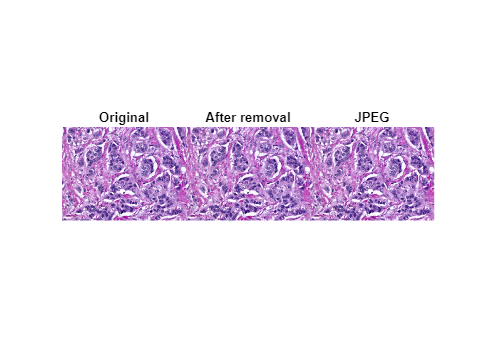

tlo = tiledlayout(fig,1,3,'TileSpacing','none');
for i = 1:numel(cropped)
    ax = nexttile(tlo); 
    imshow(cropped{i},'Parent',ax)
    title([titles(i)])
end